clear
clf
syms V(t) t m k V0 A(t)
V(t) = (V0 + 9.8*m/(k))*exp(-(k)/m*t)-9.8*m/(k);
A(t) = diff(V(t),t);

zero = solve(V(t) == 0,t);
dh = int(V(t),t,0,zero);

subs(dh,m,200)

$$ans = \frac{200\,V_{0}}{k}+\frac{392000\,\log\left(\frac{9800}{5\,V_{0}\,k+9800}\right)}{k^{2}}$$

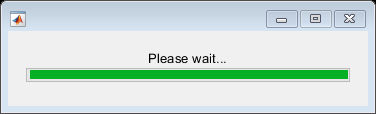


% -------------------------------------------------

k_max = 5;
k_min = 0.1;
k_step = 0.1;
num_k = (k_max - k_min) / k_step;

Vo_max = 300;
Vo_min = 1;
Vo_step = 1;
num_Vo = (Vo_max - Vo_min) / Vo_step;

res = zeros(num_k, num_Vo);
h = waitbar(0,'Please wait...');

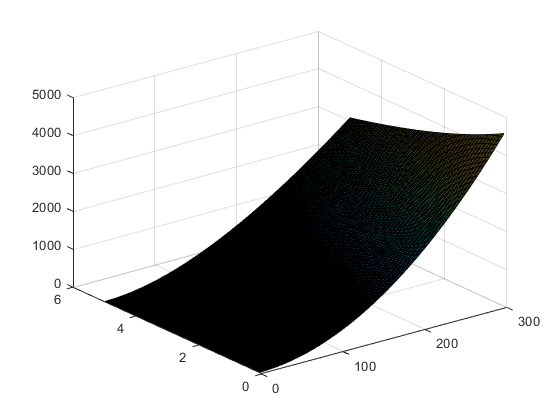

n = num_k * num_Vo;

for k_index = k_min:k_step:k_max

    for Vo_index = Vo_min:Vo_step:Vo_max
        
       res(int32(k_index / k_step), int32(Vo_index / Vo_step)) = subs(dh, [k V0 m], [k_index Vo_index 200]);
       waitbar(k_index/k_max,h);
       
    end
end

k = k_min:k_step:k_max;
Vo = Vo_min:Vo_step:Vo_max;

surf(Vo, k, res)


% -------------------------------------------------


%V(t) = subs(V(t),[V0 m c k],[200 200 10 10]);
%A(t) = subs(A(t),[V0 m c k],[200 200 10 10]);

%tStep = 1/100;
%tStop = 60;
%realV = zeros(1,tStop/tStep + 1)
%realV(1) = V(0);
%h = waitbar(0,'Please wait...');
%const = -1 + tStop/tStep;
%for n = 2:1 + tStop/tStep
%    realV(n) = realV(n - 1) + (A(n*tStep) + A((n-1)*tStep))*tStep/2;
%    waitbar(n/const,h)
%end
%tempT = 0:tStep:tStop;
%plot(tempT,realV)
%hold on
%fplot(V(t),[0 tStop])
%hold off
%plot(abs(realV(int8(tempT/tStep + 1)) - V(tempT)))